cd('/Volumes/PcSSDA/AChMut/20220714_PM28_123_AChmut_RvR_001')
ExperimentName='20220714_PM28_123_AChmut_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='123'

mouse = '123'


analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'_20220802.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

filename=[analysis_name,num2str(i),'_20220802.mat'];
load(filename)

time_csv=[analysis_name,num2str(i),'_time.csv'];
intensity_csv=[analysis_name,num2str(i),'_intensity.csv'];
lft_fit_csv=[analysis_name,num2str(i),'_tau_fitting.csv'];
lft_emp_csv=[analysis_name,num2str(i),'_tau_emp.csv'];

csvwrite(time_csv,time);
csvwrite(intensity_csv,photoncount);
csvwrite(lft_fit_csv,tau_avg);
csvwrite(lft_emp_csv,tau_empTrunc);


i=1;
filename=[analysis_name,num2str(i),'_20220802.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)

FLP_all = 3493×4 table
     time     intensity     tau_empirical    tau_fit
    ______    __________    _____________    _______

     1.012    2.6739e+05       4.2762        2.3977 
     2.232    2.6686e+05       4.2704        2.3837 
     3.253    2.6794e+05       4.2626        2.3837 
     4.272     2.681e+05       4.2695        2.3837 
     5.293    2.6777e+05       4.2607        2.3837 
     6.312     2.667e+05       4.2644        2.3852 
     7.332    2.6732e+05       4.2557        2.3852 
     8.352    2.6741e+05       4.2678        2.3852 
     9.373    2.6629e+05       4.2763         2.385 
    10.392    2.6787e+05         4.27         2.385 
    11.413    2.6888e+05       4.2623        2.3804 
    12.432    2.6687e+05       4.2631        2.3804 
    13.453    2.6735e+05       4.2682        2.3804 
    14.472      2.67e+05       4.2617        

FLP_all_csv=[analysis_name,'FLP.csv']

FLP_all_csv = '20220714_PM28_123_AChmut_RvR_001_analysis_FLP.csv'

writetable(FLP_all, FLP_all_csv)

speed_csv=['speed/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

time_of_speed_seconds=[];
time_of_speed_string=string;
reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)]

reference_time = '2022-07-14 14:01:00.3451520'

reference_time=datetime(reference_time)

reference_time = datetime
   14-Jul-2022 14:01:00



for i=1:size(time_of_speed,1)
    hour_num=str2num(time_of_speed{i}(12:13));
    min_num=str2num(time_of_speed{i}(15:16));
    sec_num=str2num(time_of_speed{i}(18:27));
    time_of_speed_seconds(i)=3600*hour_num+60*min_num+sec_num;
%     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
%     time_of_speed_string(i)=a;
%     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
end


time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);


figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


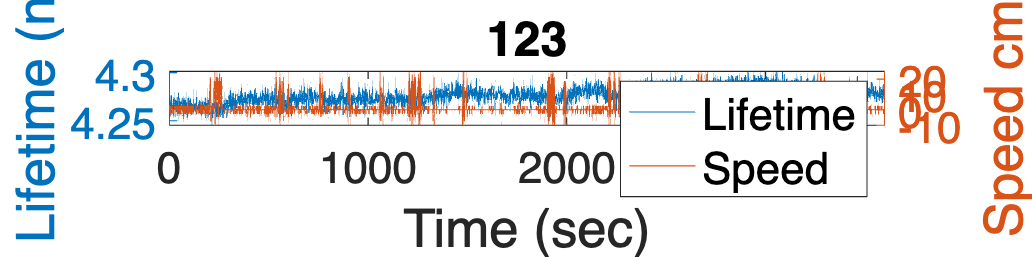

yyaxis left
plot(time,tau_empTrunc);
ylabel('Lifetime (ns)','FontSize',24)
% ylim([4.14 4.26])
% yticks([4.15 4.20 4.25 4.3])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Lifetime','Speed','FontSize',20)
title([mouse])


figure2=figure;
figure2.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


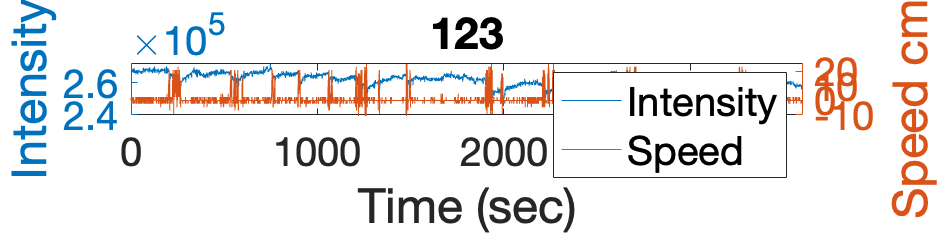

yyaxis left
plot(time,photoncount);
ylabel('Intensity','FontSize',24)
% ylim([550000 680000])
% yticks([550000 600000 650000])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Intensity','Speed','FontSize',20)
title([mouse])

cd('/Volumes/PcSSDA/AChMut/20220714_PM29_111_AChmut_RvR_002')
ExperimentName='20220714_PM29_111_AChmut_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='111'

mouse = '111'


analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'_20220802.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

filename=[analysis_name,num2str(i),'_20220802.mat'];
load(filename)

time_csv=[analysis_name,num2str(i),'_time.csv'];
intensity_csv=[analysis_name,num2str(i),'_intensity.csv'];
lft_fit_csv=[analysis_name,num2str(i),'_tau_fitting.csv'];
lft_emp_csv=[analysis_name,num2str(i),'_tau_emp.csv'];

csvwrite(time_csv,time);
csvwrite(intensity_csv,photoncount);
csvwrite(lft_fit_csv,tau_avg);
csvwrite(lft_emp_csv,tau_empTrunc);

i=1;
filename=[analysis_name,num2str(i),'_20220802.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)

FLP_all = 3493×4 table
     time     intensity     tau_empirical    tau_fit
    ______    __________    _____________    _______

     1.013      4.03e+05       4.1989        2.3266 
     2.434    4.0324e+05       4.1953        2.3246 
     3.453    4.0234e+05       4.1981        2.3243 
     4.473    4.0382e+05        4.201        2.3244 
     5.493    4.0253e+05       4.2002        2.3244 
     6.514    4.0274e+05       4.2096        2.3313 
     7.533    4.0231e+05       4.1998        2.3313 
     8.554    4.0259e+05        4.195        2.3295 
     9.573    4.0076e+05        4.197        2.3295 
    10.593    4.0258e+05       4.1966        2.3295 
    11.614    4.0274e+05       4.1962        2.3295 
    12.633    4.0261e+05       4.2022        2.3295 
    13.653    4.0299e+05       4.2021        2.3295 
    14.673    4.0034e+05       4.1971        

FLP_all_csv=[analysis_name,'FLP.csv']

FLP_all_csv = '20220714_PM29_111_AChmut_RvR_002_analysis_FLP.csv'

writetable(FLP_all, FLP_all_csv)

speed_csv=['speed/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

time_of_speed_seconds=[];
time_of_speed_string=string;
reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)]

reference_time = '2022-07-14 16:01:04.9521152'

reference_time=datetime(reference_time)

reference_time = datetime
   14-Jul-2022 16:01:04



for i=1:size(time_of_speed,1)
    hour_num=str2num(time_of_speed{i}(12:13));
    min_num=str2num(time_of_speed{i}(15:16));
    sec_num=str2num(time_of_speed{i}(18:27));
    time_of_speed_seconds(i)=3600*hour_num+60*min_num+sec_num;
%     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
%     time_of_speed_string(i)=a;
%     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
end


time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);


figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


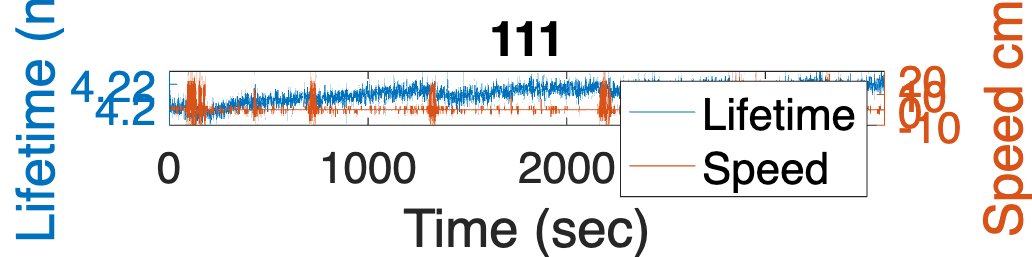

yyaxis left
plot(time,tau_empTrunc);
ylabel('Lifetime (ns)','FontSize',24)
% ylim([4.14 4.26])
% yticks([4.15 4.20 4.25 4.3])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Lifetime','Speed','FontSize',20)
title([mouse])


figure2=figure;
figure2.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


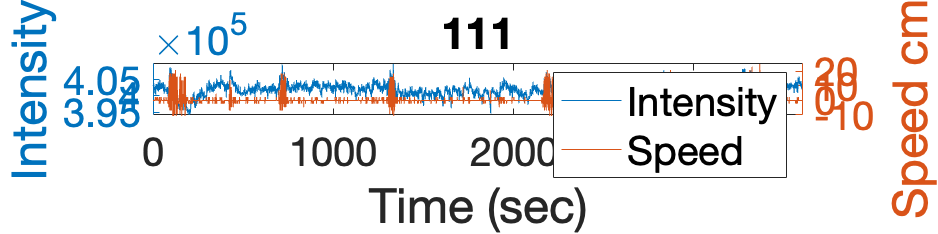

yyaxis left
plot(time,photoncount);
ylabel('Intensity','FontSize',24)
% ylim([550000 680000])
% yticks([550000 600000 650000])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Intensity','Speed','FontSize',20)
title([mouse])